# fise_otf2d

Illustrate the 2D Fourier representation of luminance images.

The Fourier transform is complex-valued.  When the image is real, the complex values obey symmetry conditions, such that


$$F(u,v) = F^*(-u,-v)$$
 

* is complex conjugate.  This implies the amplitudes at those two locations are the same.

Also, for image harmonics the mean value is positive.  So there will also be a positive value at $(0,0)$..

## ISETCam initialization

ieInit;

## Create a test image

Harmonics are very simple because they are 'points' in the transform domain.  So let's start with that.

params = harmonicP;    % Creates a struct of harmonic parameters
params.freq = 8;       % Cycles per image

params.row = 33; params.col = 33;  % Image size
scene = sceneCreate('harmonic',params);
scene = sceneSet(scene,'fov',1);   % Making it 1 deg is simple

% Spatial frequency support.
fx = sceneGet(scene,'f support x'); fullFx = [-1*fliplr(fx), fx];
fy = sceneGet(scene,'f support y'); fullFy = [-1*fliplr(fy), fy];

% Space support.
x = sceneGet(scene,'spatial support x','deg');
y = sceneGet(scene,'spatial support y','deg');

% sceneWindow(scene);

## Operate on luminance - for simplicity

One harmonic is vertical and then we create a different harmonic at 45 deg angle.

img = sceneGet(scene,'luminance');

% The 2D Fourier transform
imgF = fft2(img);

% We build up the figure
ieFigure;

tiledlayout(2,2)

nexttile
imagesc(x,y,img); axis image
xlabel('Position (deg)'); ylabel('Position (deg)');

nexttile;
imagesc(fullFx,fullFy,abs(fftshift(imgF))); 
axis equal; axis image; colormap(gray);
set(gca, 'Color', 'k'); % Set background color to black
grid on; % Turn on the grid
ax = gca; % Get current axes
ax.GridColor = [0.7 0.7 0.7]; % Set grid color to dark gray
ax.GridLineStyle = '-'; % Set grid line style
ax.LineWidth = 3; % Set grid line thickness
xlabel('Frequency (cyc/deg');
ylabel('Frequency (cyc/deg');

% A different harmonic
params.ang = 45;
[scene,parms] = sceneCreate('harmonic',params);
scene = sceneSet(scene,'fov',1);
img = sceneGet(scene,'luminance');
imgF = fft2(img);

nexttile
imagesc(x,y,img); axis image; 
xlabel('Position (deg)'); ylabel('Position (deg)');
nexttile;
imagesc(fullFx,fullFy,abs(fftshift(imgF))); 
axis equal; axis image; colormap(gray);
set(gca, 'Color', 'k'); % Set background color to black
grid on; % Turn on the grid
ax = gca; % Get current axes
ax.GridColor = [0.7 0.7 0.7]; % Set grid color to dark gray
ax.GridLineStyle = '-'; % Set grid line style
ax.LineWidth = 3; % Set grid line thickness
xlabel('Frequency (cyc/deg');
ylabel('Frequency (cyc/deg');

%{
% Write out the figure as a PNG.
theDir = fullfile(fiseRootPath,'chapters','images','optics');
exportgraphics(gcf,fullfile(theDir,'otf2d.png'));
%}

## A face image

Force the scene to have an odd number of rows and columns.  Also 10 deg, which is more typical of viewing distance and sampling density.

scene = sceneFromFile('faceMale.jpg','rgb',[],displayCreate);
scene = sceneSet(scene,'fov',10);
imSize = sceneGet(scene,'size');
newSize = round(imSize/2)*2 - 1;
scene = sceneCrop(scene,[1 1 newSize(1)-1 newSize(2)-1]);

% Spatial frequency support.
fx = sceneGet(scene,'f support x'); fullFx = [-1*fliplr(fx), fx];
fy = sceneGet(scene,'f support y'); fullFy = [-1*fliplr(fy), fy];

% Space support.
x = sceneGet(scene,'spatial support x','deg');
y = sceneGet(scene,'spatial support y','deg');

% sceneWindow(scene);
img = sceneGet(scene, 'luminance');


## Display the loaded face image

Shows the images and corresponding Fourier Transform amplitude representations in the top and bottom rows.

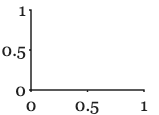

ieFigure;

subplot(2,3,1);

imagesc(x,y,img); axis image
xlabel('Position (deg)'); ylabel('Position (deg)');
drawnow;

% Now the log of the FFT amplitude.
subplot(2,3,4);
imgF = fft2(img);
imagesc(fullFx,fullFy,log10(abs(fftshift(imgF)))); 
axis equal; axis image; colormap(gray);
set(gca, 'Color', 'k'); % Set background color to black
grid on; % Turn on the grid
ax = gca; % Get current axes
ax.GridColor = [0.7 0.7 0.7]; % Set grid color to dark gray
ax.GridLineStyle = '-'; % Set grid line style
ax.LineWidth = 3; % Set grid line thickness
xlabel('Frequency (cyc/deg)');
ylabel('Frequency (cyc/deg)');
drawnow;
%{
% Show that we can invert the FFT to reconstruct the image
nexttile
imagesc(x,y,fliplr(abs(fft2(imgF)))); % Corrected to display the magnitude of the Fourier transform
axis equal; axis xy; axis off
title('Reconstructed image.');
%}

%% Create a Gaussian kernel 
% Reduce low frequency terms 
% mesh(FX,FY,lowFreqReduction);

[FX, FY] = meshgrid(fullFx(1:(end-1)), fullFy(1:(end-1)));

% Standard deviation for the Gaussian
sigma = 0.6;   
lowFreqReduction = 1 - exp(-(FX.^2 + FY.^2) / (2 * sigma^2));

%% Apply the Gaussian kernel to imgF, worrying about the fftshift
subplot(2,3,2);
imgF_reduced = fftshift(imgF) .* (lowFreqReduction);
imagesc(x,y,fliplr(abs(fft2(fftshift(imgF_reduced))))); % Corrected to display the magnitude of the Fourier transform
axis equal; axis xy; axis off
drawnow;

% Show the scaled FFT
subplot(2,3,5);
imagesc(fullFx,fullFy,log10(abs(imgF_reduced))); 
axis equal; axis image; colormap(gray);
set(gca, 'Color', 'k'); % Set background color to black
grid on; % Turn on the grid
ax = gca; % Get current axes
ax.GridColor = [0.7 0.7 0.7]; % Set grid color to dark gray
ax.GridLineStyle = '-'; % Set grid line style
ax.LineWidth = 3; % Set grid line thickness
drawnow;

% Flip the reduction
subplot(2,3,3);
imgF_reduced = fftshift(imgF) .* (1-lowFreqReduction);
imagesc(x,y,fliplr(abs(fft2(fftshift(imgF_reduced))))); % Corrected to display the magnitude of the Fourier transform
axis equal; axis xy; axis off

% Show the transform itself
subplot(2,3,6);
imagesc(fullFx,fullFy,log10(abs(imgF_reduced))); 
axis equal; axis image; colormap(gray);
set(gca, 'Color', 'k'); % Set background color to black
grid on; % Turn on the grid
ax = gca; % Get current axes
ax.GridColor = [0.7 0.7 0.7]; % Set grid color to dark gray
ax.GridLineStyle = '-'; % Set grid line style
ax.LineWidth = 3; % Set grid line thickness
drawnow;

%{
theDir = fullfile(fiseRootPath,'chapters','images','optics');
exportgraphics(gcf,fullfile(theDir,'otf2dParts.png'));
%}

## End